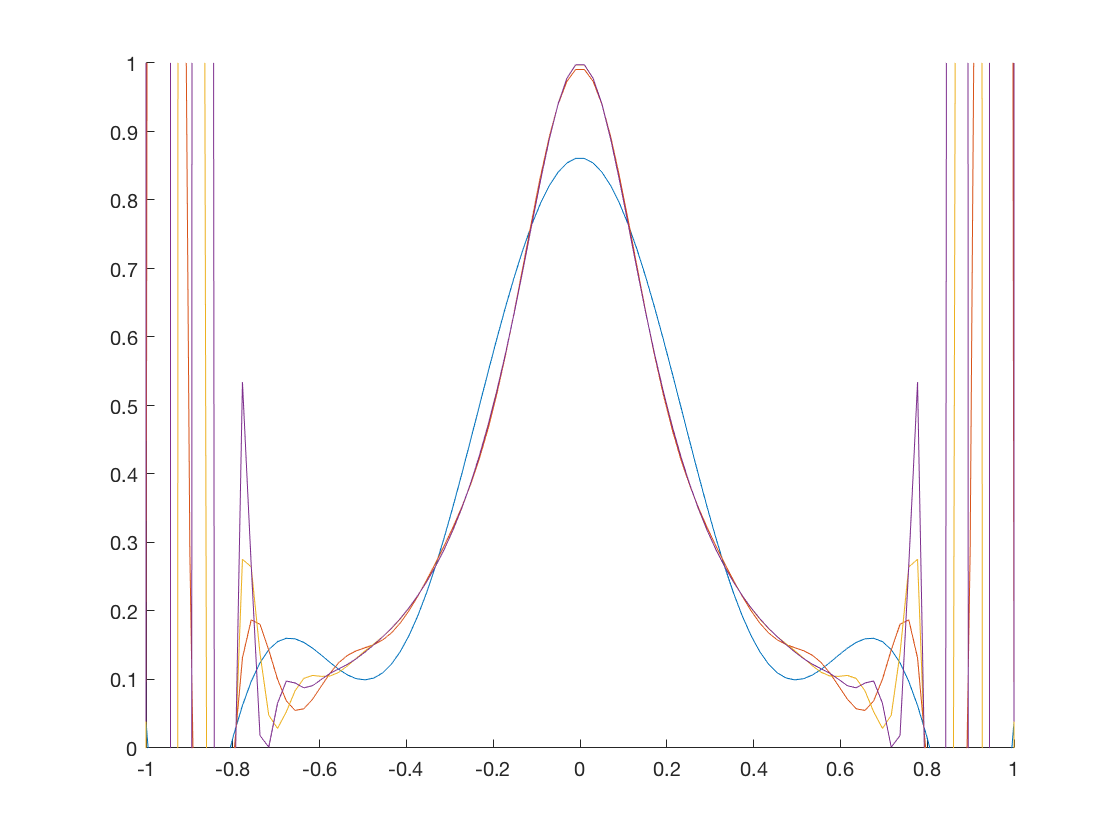

%Number 1A
% Yes, increasing the number of sample points gives a
% better approximation as it looks less choppy.
f = @(x) (1./(1+25*x.^2));
X = linspace(-1,1,100);
Y = f(X);
y1 = 0;
% plot(X,Y); 
n = (10:10:40); %array of [10,20,30,40]


for i=1:length(n)
    x = linspace(-1,1,n(i));
    y = f(x);
    for j = 1:length(X)
       y1(j) = linterp(x,y,X(j)); 
    end
    %Plot making/ Legend making
    hold on;
    plot(X,y1);
    ylim([0,1.5]);
    s{1} = "Exact Function";
    % each line will get its own entry S{i}
    s{i+1} = sprintf('%d points',10*i);
    legend(s);
end

%Number

function y = linterp(X,Y,x)
y = 0;
for i = 1:numel(X)
    yy = Y(i);
    for j = 1:numel(X)
        if i~=j
            yy = yy .* (x-X(j))/(X(i)-X(j));
        end
    end
    y = y+yy;
end
end